# Project 1

## Part 1

### Problem 1

#### Part A

#### Part B

clear; clc;

syms x
g(x) = exp(-x);
g_prime(x) = diff(g, x);

a = 1/exp(1);
b = 1;

vpa(a, 4)

$$ans = 0.3679$$

vpa(b, 4)

$$ans = 1.0$$

vpa(g(a), 4)

$$ans = 0.6922$$

vpa(g(b), 4)

$$ans = 0.3679$$

vpa(g_prime(a), 4)

$$ans = -0.6922$$

#### Part C

p_0 = 0.4;
TOL = 10^-6;

[p_vec, p] = fixedPoint(g, p_0, TOL);

n              p_n            |p_n-p_{n-1}|  
1              0.67032        0.27032        
2              0.51154        0.15878        
3              0.59957        0.088024       
4              0.54905        0.05052        
5              0.5775         0.028451       
6              0.5613         0.016199       
7              0.57047        0.0091664      
8              0.56526        0.0052052      
9              0.56821        0.00295        
10             0.56654        0.0016737      
11             0.56749        0.00094903     
12             0.56695        0.00053831     
13             0.56725        0.00030528     
14             0.56708        0.00017314     
15             0.56718        9.8194e-05     
16             0.56712        5.5691e-05     
17             0.56715        3.1584e-05     
18             0.56714        1.7913e-05     
19             0.56715        1.0159e-05     
20             0.56714        5.7617e-06     
21             0.56714        3.26

#### Part D

const = [];

for n = 1:23

    const(n) = abs(p_vec(n+1) - p)/abs(p_vec(n) - p);

end

vpa(const', 5)

$$ans = \left(\begin{array}{c} 0.53886\\ 0.58321\\ 0.55804\\ 0.57232\\ 0.56418\\ 0.56886\\ 0.5661\\ 0.56786\\ 0.56652\\ 0.56787\\ 0.56606\\ 0.56894\\ 0.56406\\ 0.57258\\ 0.55768\\ 0.58411\\ 0.53811\\ 0.62109\\ 0.48028\\ 0.74799\\ 0.32537\\ 1.3102\\ 0 \end{array}\right)$$

### Problem 2

#### Part A

clear; clc;

syms x
g(x) = exp(-x);

p_0 = 0.4;
TOL = 10^-6;

[p_vec, p] = SteffensenMethod(g, p_0, TOL);

n              p_n            |p_n-p_{n-1}|  
1              0.5703         0.1703         
2              0.56714        0.003151       
3              0.56714        1.0178e-06     
4              0.56714        1.0633e-13     


#### Part B

const = [];

for n = 1:3

    const(n) = abs(p_vec(n+1) - p)/abs(p_vec(n) - p)^2;

end

vpa(const', 5)

$$ans = \left(\begin{array}{c} 0.10244\\ 0.10262\\ 0 \end{array}\right)$$

## Part 2

### Problem 1

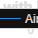

clear; clc;

syms x

y(x) = 2.969*sqrt(x) - 1.26*x - 3.516*x^2 + 2.843*x^3 - 1.015*x^4;

figure
fplot(y, [0, 1])
axis([0 1 0 4])
title("Airfoil with L.E. at x=0")
xlabel("Distance from L.E.")
ylabel("Airfoil Thickness")
legend("Airfoil Profile", "Location", "best")

### Problem 2

#### Part A

clear; clc;

syms x

y(x) = 2.969*sqrt(x) - 1.26*x - 3.516*x^2 + 2.843*x^3 - 1.015*x^4;
y_prime(x) = diff(y, x);

vpa(y_prime)

$$ans(x) = 8.529\,x^{2}-7.032\,x+\frac{1.484}{\sqrt{x}}-4.06\,x^{3}-1.26$$

#### Part B

p_0 = 0.1;
TOL = 10^-7;

p = NewtonMethod(y_prime, p_0, TOL);

n              p_n            |p_n-p_{n-1}|  
1              0.1972486      0.09724864     
2              0.2762193      0.0789707      
3              0.2986261      0.02240674     
4              0.2998248      0.001198702    
5              0.2998279      3.103562e-06   
6              0.2998279      2.069539e-11   


### Problem 3

#### Part A

#### Part B

clear; clc;

syms x

y(x) = 2.969*sqrt(x) - 1.26*x - 3.516*x^2 + 2.843*x^3 - 1.015*x^4;
y_prime(x) = diff(y, x) + x;

p_0 = 0.1;
TOL = 10^-7;

[p_vec, p] = SteffensenMethod(y_prime, p_0, TOL);

n              p_n            |p_n-p_{n-1}|  
1              0.25318        0.15318        
2              0.33455        0.081362       
3              0.31674        0.017805       
4              0.30374        0.012996       
5              0.30004        0.0037032      
6              0.29983        0.00021297     
7              0.29983        6.4019e-07     
8              0.29983        5.7534e-12     


vpa(p_vec)

$$ans = \left(\begin{array}{cccccccc} 0.2532 & 0.3345 & 0.3167 & 0.3037 & 0.3 & 0.2998 & 0.2998 & 0.2998 \end{array}\right)$$

#### Part C

y(x) = 2.969*sqrt(x) - 1.26*x - 3.516*x^2 + 2.843*x^3 - 1.015*x^4;
y_prime(x) = diff(y, x);

f(x) = (y_prime(x + y_prime(x)) - y_prime(x))/y_prime(x);
g(x) = x - y_prime(x)/f(x);
g_prime(x) = diff(g, x);

vpa(g_prime(p_vec'))

$$ans = \left(\begin{array}{c} -1.563\\ 1.043\\ 0.4613\\ 0.1087\\ 0.005993\\ 1.797e-5\\ 0.03098\\ 0.08628 \end{array}\right)$$